close all;
clear all;
w = 2*pi;
f = w/(2*pi);
period = 1/f;
dt = 0.001;
t = (0:dt:10)';
fa = 0*ones(size(t));
fb = 90*ones(size(t));
fa2 = 50*ones(size(t))+0*t;
fb2 = 45*ones(size(t));
fa3 = 5*ones(size(t));
fb3 = 4.5*ones(size(t));
wave = fa.*cos(w*t) + fb.*sin(w*t) + fa2.*cos(2*w*t) + fb2.*sin(2*w*t)+ fa3.*cos(3*w*t) + fb3.*sin(3*w*t);

a_vec = [fa; fa2; fa3];
b_vec = [fb; fb2; fb3];

t_pre = unique(trial_out.t(1:end/2), "stable");
wave_pre = unique(trial_out.X(1:end/2,1), "stable");

t = linspace(t_pre(1), t_pre(end), round(length(t_pre)/100))';
wave = 100*interp1(t_pre, wave_pre, t);


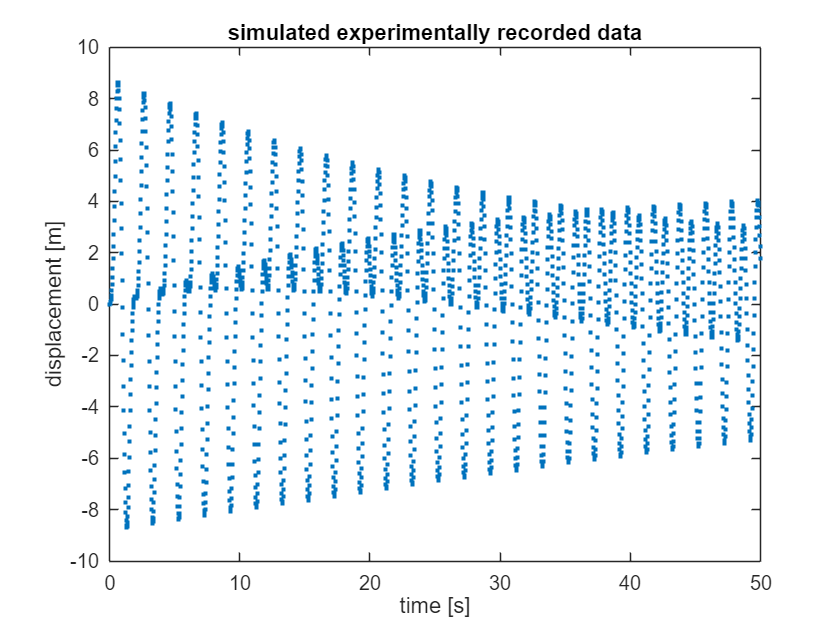

figure;
plot(t, wave, '.')
title("simulated experimentally recorded data");
xlabel("time [s]");
ylabel("displacement [m]");

% now lets go through the data step by step and estimate A and B
dt = t(2)-t(1)

dt = 0.0249

w0 = 2*pi

w0 = 6.2832

z = fft(wave);
[a,b] = get_fft_components(t', wave', w0, 5)

a =     0.0738
   -0.2426
   -0.0057
   -0.0028
   -0.0019
   -0.0015


b =          0
   -3.3976
   -0.0042
   -0.0028
   -0.0021
   -0.0016


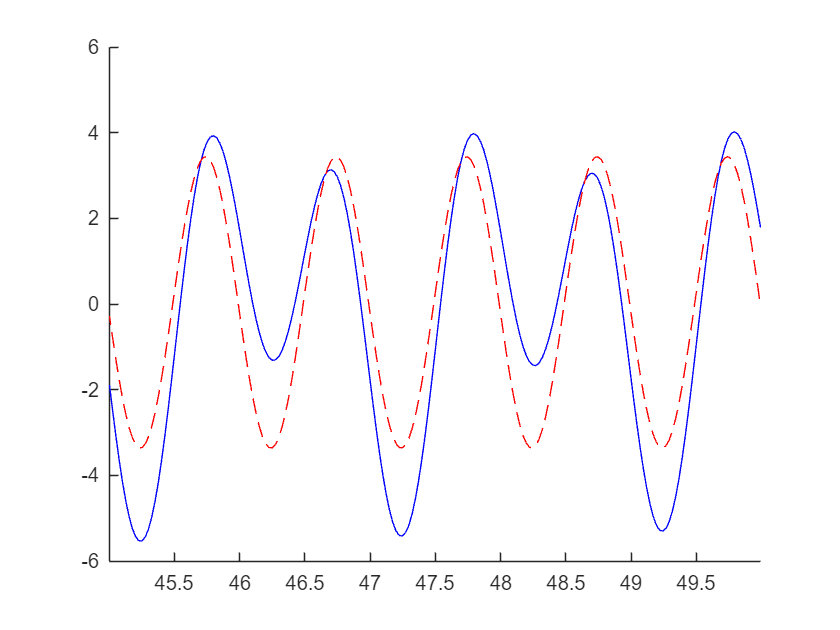

w0 = 2*pi;
% t_lin = linspace(t(1), t(end), round(length(t)/100))';
% x_lin = interp1(t, wave, 0);
figure;
hold on;
plot(t, wave, 'b-')
[t_lin, x_reconstructed] = get_reconstructed_wave(a, b, t, w0);

plot(t_lin, x_reconstructed, 'r--')
xlim([t(round(length(t)*0.9)), t(end)])

% Initialize amplitude estimation
input.w0 = w0;
trial_next.dt = dt;
trial_next.k = 2;
trial_next.A = zeros(trial_next.k,length(t));
trial_next.B = zeros(trial_next.k,length(t));
trial_next.A_smooth = zeros(size(trial_next.A));
trial_next.B_smooth = zeros(size(trial_next.B));
% trial_next = rmfield(trial_next, "house");

for i = (1:length(t)-1)
    trial_parameter = trial_next;
    sum(trial_parameter.A(1, :) ~= 0);
    % get current reading
    time = t(i);
    x_n = wave(i);
    trial_parameter.A;
    [trial_next] = get_iterative_coeffs(i, time, x_n, input, trial_parameter);

    A_next = trial_next.A(:, i+1);
    B_next = trial_next.B(:, i+1);
    % % trial.A(:, i+1) = A_next;
    % % trial.B(:, i+1) = B_next;
    % % trial_next = trial;
    % 
    % trial_next.A(:, i+1) = A_next;
    % trial_next.B(:, i+1) = B_next;
    % trial_next.B(:, i+1)


    for k = (1:size(trial_next.A(:, i+1), 1))
        alpha = 0.005; % Smoothing factor (0 < alpha <= 1)
        a_s = filter(alpha, [1 alpha-1], trial_next.A(k, 1:i+1));
        b_s = filter(alpha, [1 alpha-1], trial_next.B(k, 1:i+1));
        trial_next.A_smooth(k, i+1) = a_s(end);
        trial_next.B_smooth(k, i+1) = b_s(end);
    end
end

% trial = trial_next;
% trial.A(:, end)

% figure;
tiledlayout(2, 1, "TileSpacing", "compact");
nexttile;
plot(t, wave, 'k')
title("Response curve")

nexttile;

hold on;

for i = (1:size(trial_next.A, 1))
    plot(t, trial_next.A(i, :))
    plot(t, trial_next.B(i, :))

    plot(t, trial_next.A_smooth(i, :), "LineWidth",2)
    plot(t, trial_next.B_smooth(i, :), "LineWidth",2)

    plot([0, t(end)], [1 1].*a(i+1), 'r--', lineWidth=0.5)
    plot([0, t(end)], [1 1].*b(i+1), 'r--', lineWidth=0.5)
end

legend(["a1", "b1", "a1s", "b1s", "a1r", "b1r", "a2", "b2", "a2s", "b2s", "a2r", "b2r", "a3", "b3", "a3s", "b3s", "a3r", "b3r"], location="bestoutside")

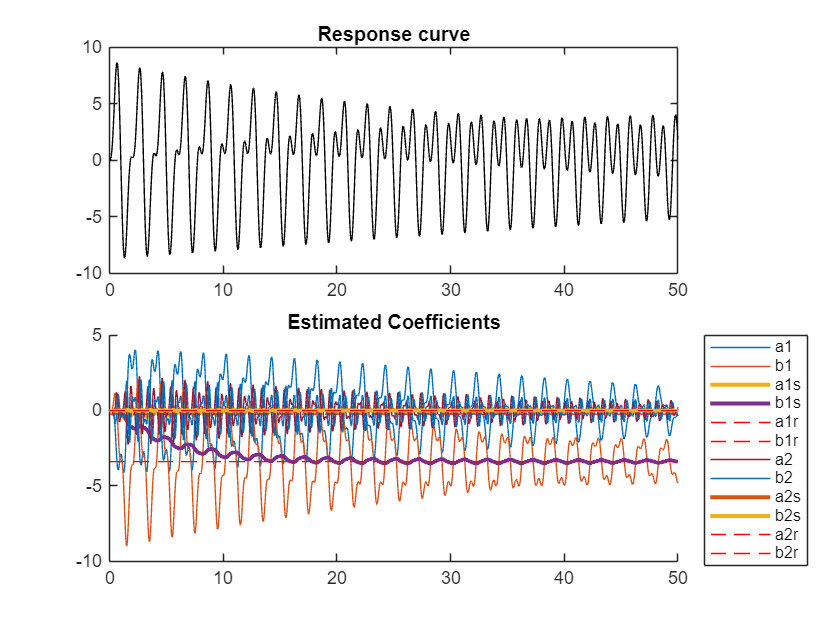


% plot([0, t(end)], [1 1].*a(2), 'r--', lineWidth=0.5)
% plot([0, t(end)], [1 1].*b(2), 'r--', lineWidth=0.5)

title("Estimated Coefficients")




house.k = 3;    % number of harmonics

A = zeros(house.k,length(t));
B = zeros(house.k,length(t));

A_smooth = zeros(size(A));
B_smooth = zeros(size(B));

w = 2*pi;
dt = t(2)-t(1)

dt = 0.0249


% create windows of appropriate length for each harmonic
for j = (1:house.k)
    house.w(j) = w*j;
    house.T(j) = 2*pi/(w*1); %using a window length of period of 1st harmonic gives best result
    
    win_len = round(house.T(j)/dt);
    house.A{j} = zeros(1, win_len);
    house.B{j} = zeros(1, win_len);
end

% go through data points in order... 1 by 1
for i = (1:length(t)-1)
    % get current reading
    time = t(i);
    x_n = wave(i);
    A
    for k = (1:house.k)
        add_A = (2 * dt / house.T(k)) * x_n * cos(house.w(k) * time);
        add_B = (2 * dt / house.T(k)) * x_n * sin(house.w(k) * time);
        
        A(k,i+1) = A(k, i) + add_A - house.A{k}(1);
        A(k,i+1)
        B(k,i+1) = B(k, i) + add_B - house.B{k}(1);

        house.A{k} = circshift(house.A{k}, -1);
        house.B{k} = circshift(house.B{k}, -1);

        house.A{k}(end) = add_A;
        house.B{k}(end) = add_B;

        x_recon = A(k,i+1).*cos(house.w(k)*time) + B(k,i+1).*sin(house.w(k)*time);
        x_n = x_n - x_recon;

        alpha = 0.005; % Smoothing factor (0 < alpha <= 1)
        a_s = filter(alpha, [1 alpha-1], A(k, 1:i+1));
        b_s = filter(alpha, [1 alpha-1], B(k, 1:i+1));
        A_smooth(k, i+1) = a_s(end);
        B_smooth(k, i+1) = b_s(end);

    end
end

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 0

ans = 0

ans = 0

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 7.9971e-05

ans = 7.3175e-05

ans = 6.5154e-05

A = 1.0e-04 *

         0         0    0.7997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.7317         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

ans = 6.9306e-04

ans = 5.6583e-04

ans = 4.0369e-04

A = 1.0e-03 *

         0         0    0.0800    0.6931         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0732    0.5658         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

ans = 0.0026

ans = 0.0018

ans = 7.0377e-04

A =          0         0    0.0001    0.0007    0.0026         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0001    0.0006    0.0018         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

ans = 0.0067

ans = 0.0032

ans = -6.1142e-04

A =          0         0    0.0001    0.0007    0.0026    0.0067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0001    0.0006    0.0018    0.0032         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

ans = 0.0136


% figure;
tiledlayout(2, 1, "TileSpacing", "compact");
nexttile;
plot(t, wave, 'k')
title("Response curve")

nexttile;

hold on;

for i = (1:size(A, 1))
    plot(t, A(i, :))
    plot(t, B(i, :))

    plot(t, A_smooth(i, :), "LineWidth",2)
    plot(t, B_smooth(i, :), "LineWidth",2)

    plot([0, t(end)], [1 1].*a(i+1), 'r--', lineWidth=0.5)
    plot([0, t(end)], [1 1].*b(i+1), 'r--', lineWidth=0.5)
end

legend(["a1", "b1", "a1s", "b1s", "a1r", "b1r", "a2", "b2", "a2s", "b2s", "a2r", "b2r", "a3", "b3", "a3s", "b3s", "a3r", "b3r"], location="bestoutside")

plot([0, t(end)], [1 1].*a(2), 'r--', lineWidth=0.5)
plot([0, t(end)], [1 1].*b(2), 'r--', lineWidth=0.5)

title("Estimated Coefficients")

trial_next.B
trial.B
same = trial_next.B ~= trial.B;
find(same, 1, "first")
same(2000: 2005)